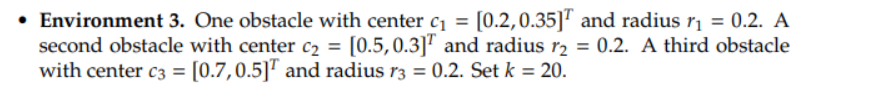

clear
close all

% start and goal
theta_start = [0;0];
theta_goal = [1;1];
centers = [0.2 0.5, 0.7; 0.35 0.3, 0.5];
radii = [0.2, 0.2, 0.2];

% initial trajectory
n = 2;
k = 10;
xi_0 = [linspace(theta_start(1), theta_goal(1), k);...
 linspace(theta_start(2), theta_goal(2), k)];
xi_0_vec = reshape(xi_0, [], 1);

% start and goal equality constraints
A = [eye(n) zeros(n, n*(k-1));...
 zeros(n, n*(k-1)), eye(n)];

B = [theta_start; theta_goal];

% nonlinear optimization
options = optimoptions('fmincon','Display','final',...
 'Algorithm','sqp','MaxFunctionEvaluations',1e5);
xi_star_vec = fmincon(@(xi) cost(xi, centers, radii), xi_0_vec, ...
 [], [], A, B, [], [], [], options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


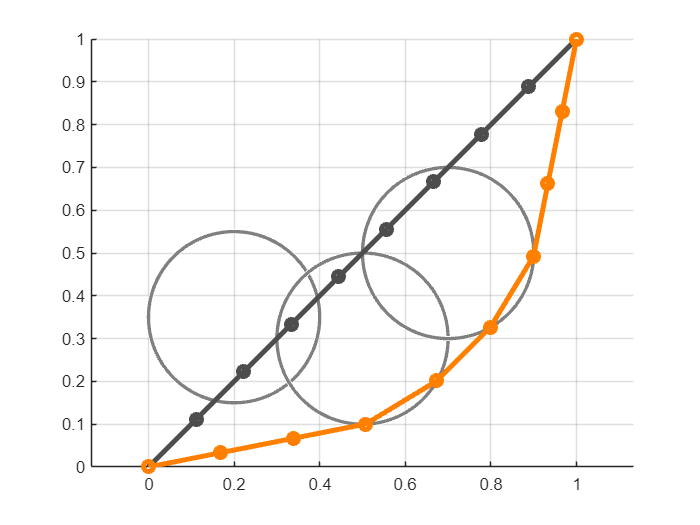

xi_star = reshape(xi_star_vec, 2, []);

% plot result
figure
grid on
hold on
axis equal
for idx = 1:length(radii)
 viscircles(centers(:, idx)', radii(idx), 'Color', [0.5, 0.5, ...
 0.5]);
end
plot(xi_0(1,:), xi_0(2,:), 'o-', 'Color', [0.3, 0.3, ...
 0.3], 'LineWidth', 3);
plot(xi_star(1,:), xi_star(2,:), 'o-', 'Color', [1, 0.5, ...
 0], 'LineWidth', 3);


% cost function to minimize

function C = cost(xi, centers, radii)
 xi = reshape(xi, 2, []);
 C = 0;
 for idx = 2:length(xi)
 theta_curr = xi(:, idx);
 theta_prev = xi(:, idx - 1);
 C = C + norm(theta_curr - theta_prev)^2;
 for jdx = 1:length(radii)
 center = centers(:, jdx);
 radius = radii(jdx);
 if norm(theta_curr - center) < radius
 C = C + 0.5*(1/norm(theta_curr - center) - 1/radius)^2;
 end
 end
 end
end